rng(0)
houseprice = readtable("housprice.xlsx")

houseprice = 24×6 table
        y         x3    x4     x1      x5     x2
    __________    __    __    ____    ____    __

     5.799e+05    5     3     4749    1120     4
    2.4988e+05    3     2     1530     330     8
     2.149e+05    3     3     2357     637     7
      1.75e+05    6     3     2337       0     3
         79900    2     2      890       0     5
      3.25e+05    3     2     1973     350     7
     1.949e+05    3     1     1232     296     4
       3.3e+05    3     2     2060      30     6
     1.999e+05    3     1     1236       0     6
      2.85e+05    4     2     2171       0     5
     3.899e+05    3     3     2868     600    10
     1.699e+05    3     2     1280     200     5
     3.649e+05    4     3     2070       0     6
     2.499e+05    2     3     1724  

x = houseprice.x1;
y = houseprice.y;
xbar = mean(x);
ybar = mean(y);

a1 = sum((x-xbar).*(y ...
    -ybar))./sum((x-xbar).^2)

a1 = 133.7565

a0 = ybar - a1.*xbar

a0 = 7.0914e+03

sigma = sqrt(sum((y - (a0+a1.*x)).^2)./(length(x)))./1.5

sigma = 4.0901e+04

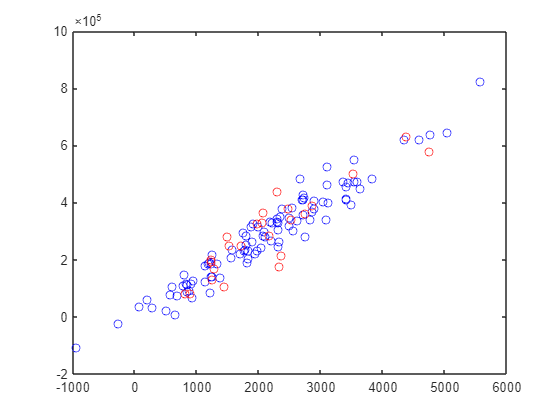


X1 = randn(100,1).*1000 + 2000;
mu = a0 + a1.*X1;
Y = normrnd(mu,sigma);
figure
plot(X1,Y,"bo")
hold on
plot(x,y,"ro")
hold off


x =  houseprice.x2;
y = houseprice.y;
xbar = mean(x);
ybar = mean(y);

a1 = sum((x-xbar).*(y-ybar))./sum((x-xbar).^2)

a1 = 2.4192e+04

a0 = ybar - a1.*xbar

a0 = 1.5876e+05

sigma = sqrt(sum((y - (a0+a1.*x)).^2)./(length(x)))./5

sigma = 2.7066e+04

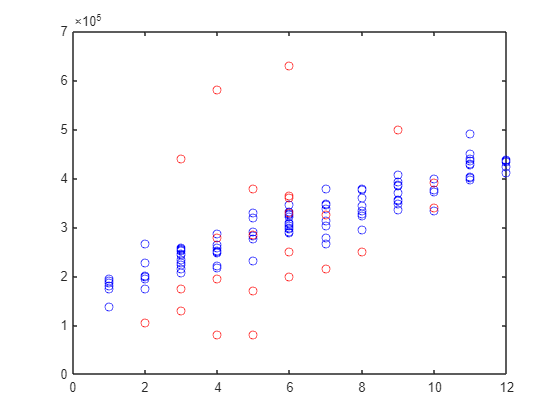


X2 = randi(12,[100,1]);
mu = a0 + a1.*X2;
Ynew = normrnd(mu,sigma);
figure
plot(X2,Ynew,"bo")
hold on
plot(x,y,"ro")
hold off

T1 = table(X1,Y);
T2 = table(X2,Ynew);
T1 = sortrows(T1,2);
T2 = sortrows(T2,2);
T = [];
for k = 1:height(T1)
    idx = abs(T2.Ynew-T1.Y(k)) <= 0.005*(T1.Y(k));
    if any(idx)
        T = [T;[T2{find(idx,1,"first"),:},T1{k,:}]];
    end
end
T = array2table(T,'VariableNames',{'X1','Y1','X2','Y2'})

T = 39×4 table
    X1        Y1          X2          Y2    
    __    __________    ______    __________

    1     1.7976e+05    1136.3    1.8036e+05
    3     2.0685e+05      1561    2.0731e+05
    3     2.2291e+05    1936.9    2.2232e+05
    3     2.2291e+05    1696.6    2.2265e+05
    5     2.3086e+05    1969.9    2.3053e+05
    5     2.3086e+05    1822.6     2.314e+05
    5     2.3086e+05    1758.6    2.3159e+05
    3      2.435e+05    2032.6    2.4428e+05
    3     2.4585e+05    2319.2    2.4571e+05
    4     2.5215e+05      1795    2.5226e+05
    4      2.637e+05    2325.2    2.6355e+05
    7     2.6533e+05    2197.8    2.6635e+05
    7     2.7841e+05    2748.1    2.7937e+05
    7     2.7841e+05    2104.9    2.7973e+05
    8     2.9459e+05    1756.3    2.9357e+05
    6     2.9823e+05    2085.9    2.9868e+05



T = normalize(T);
fitlm([T.X1,T.X2],T.Y1,"interactions")

ans = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)    0.0081147    0.076116     0.10661       0.91571
    x1               0.61033    0.098997      6.1651    4.6822e-07
    x2               0.37322     0.09934       3.757    0.00062664
    x1:x2          -0.010747    0.059416    -0.18087       0.85751


Number of observations: 39, Error degrees of freedom: 35
Root Mean Squared Error: 0.384
R-squared: 0.864,  Adjusted R-Squared: 0.853
F-statistic vs. constant model: 74.2, p-value = 3.02e-15

fitlm(T.X1,T.Y1)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    5.5075e-17    0.070905    7.7675e-16             1
    x1                0.89949    0.071832        12.522    7.1407e-15


Number of observations: 39, Error degrees of freedom: 37
Root Mean Squared Error: 0.443
R-squared: 0.809,  Adjusted R-Squared: 0.804
F-statistic vs. constant model: 157, p-value = 7.14e-15

fitlm(T.X2,T.Y1)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE          tStat         pValue  
                   __________    ________    ___________    __________

    (Intercept)    -1.291e-16    0.086717    -1.4888e-15             1
    x1                0.84525     0.08785         9.6215    1.2996e-11


Number of observations: 39, Error degrees of freedom: 37
Root Mean Squared Error: 0.542
R-squared: 0.714,  Adjusted R-Squared: 0.707
F-statistic vs. constant model: 92.6, p-value = 1.3e-11

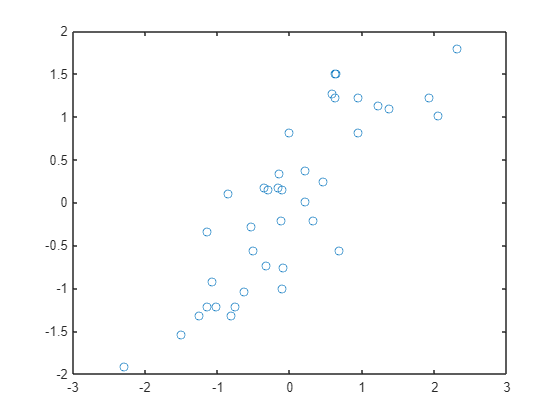


plot(T.X2,T.Y1,"o")

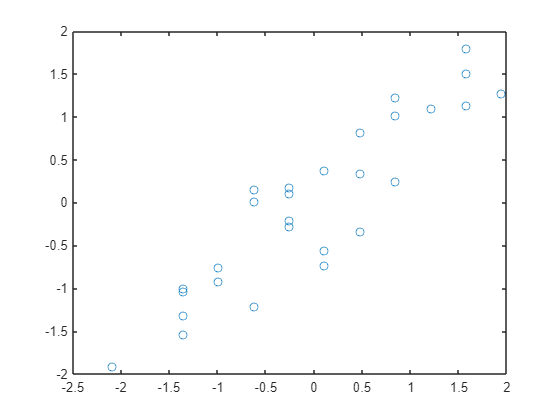

plot(T.X1,T.Y1,"o")

Mdl = fitlm([T.X1,T.X2],T.Y1,"interactions")

Mdl = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)    0.0081147    0.076116     0.10661       0.91571
    x1               0.61033    0.098997      6.1651    4.6822e-07
    x2               0.37322     0.09934       3.757    0.00062664
    x1:x2          -0.010747    0.059416    -0.18087       0.85751


Number of observations: 39, Error degrees of freedom: 35
Root Mean Squared Error: 0.384
R-squared: 0.864,  Adjusted R-Squared: 0.853
F-statistic vs. constant model: 74.2, p-value = 3.02e-15

coeffs = Mdl.Coefficients.Estimate

coeffs =     0.0081
    0.6103
    0.3732
   -0.0107


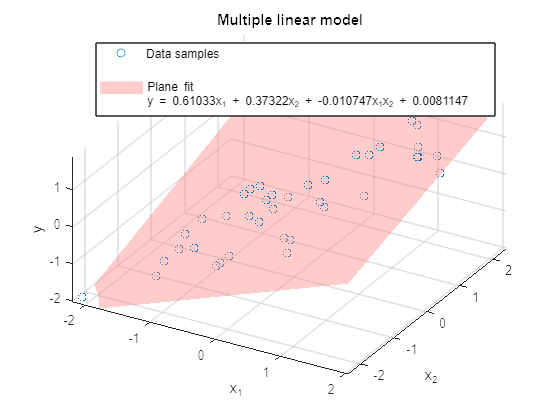

 

plotMultiFit(T.X1,T.X2,T.Y1,coeffs);
view(30,45)

function yhat = plotMultiFit(x1,x2,y,coeffs)

% Split the coefficients into individual variables and estimate y.
[a,b,c,d] = deal(coeffs(2),coeffs(3),coeffs(4),coeffs(1));
yhat = a.*x1 + b.*x2 + c.*x1.*x2 + d;

% Plot
scatter3(x1,x2,y);
xlim([min(x1)-0.1,max(x1)+0.1]);
ylim([min(x2)-0.1,max(x2)+0.1]);
zlim([min(y)-0.1,max(y)+0.1]);
[X1,X2] = meshgrid(xlim,ylim);
hold on
surf(X1,X2,a.*X1 + b.*X2 + c.*X1.*X2 + d,"FaceAlpha", 0.4,"FaceColor",[1 0.5 0.5],"EdgeColor","none");
hold off
% Annotate
title("Multiple linear model")
dispPlane = sprintf("\nPlane fit"+"\ny = " + a + "x_{1} + " + b + "x_{2} + " + c + "x_{1}x_{2} + " + d);
legend("Data samples",dispPlane,"Location","northeast");
view([-150 20])
xlabel('x_{1}'), ylabel('x_{2}'), zlabel("y")

end
